# Homework 7 (Solution) 

Math 3607

Tae Eun Kim

clear, close all, format short 

## Problem 1 (FNC 4.1.4)

Let's write a script solving the problem for a single $P$ value:

P = 500;
n = 300;
FV = 1e6;  % value at maturity

We need to find an interest rate $r$ which satisfies

$\displaystyle \frac{12P}{r} \left( \left( 1 + \frac{r}{12} \right)^n - 1 \right) = 1,000,000$.

In other words, $r$ is a root of 

$\displaystyle f( r ) = \frac{12P}{r} \left( \left( 1 + \frac{r}{12} \right)^n - 1 \right) - 1,000,000$.

f = @(r) 12*P/r*( (1+r/12)^n - 1 ) - FV; % objective function
r = fzero(f, 0.01)                       % use 0.01 as an initial guess 

r = 0.1235

Now we carry out the same computation for $P = 500, 550, ... 1000$, while all other parameters are fixed.

n = 300;
FV = 1e6;
P = 500:50:1000;
for j = 1:length(P)
    f = @(r) 12*P(j)/r*( (1+r/12)^n - 1 ) - FV;
    r = fzero(f, 0.01);
    if j == 1
        fprintf(' %4s %8s\n', 'P', 'r')
        fprintf(' %13s\n', repmat('-', 1, 13))
    end
    fprintf(' %4d %8.4f\n', P(j), r)
end

    P        r


 -------------


  500   0.1235
  550   0.1181
  600   0.1132
  650   0.1086
  700   0.1043
  750   0.1003
  800   0.0965
  850   0.0929
  900   0.0895
  950   0.0862
 1000   0.0831


## Problem 2 (FNC 4.1.6, Lambert's W function)

Since $y = W(x)$ iff $x = y e^y$, $y$ is a root of $f(y) = x - ye^y$ for a given $x$, which can be found using `fzero` as follows:

Thus we can write a MATLAB function which computes $W(x)$ by

Note that the function can take an array input `x` and produce corresponding values in an array `y` of the same dimensions as `x`. So we can use this function just as any other built-in mathematical functions, say to plot its graph:

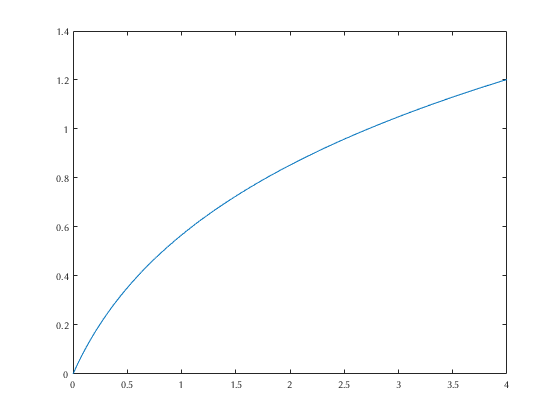

x = linspace(0, 4, 100);
plot(x, lambertW(x))

**Note.** MATLAB actually comes with this function; it is named `lambertw`. Let's compare:

norm( lambertW(x) - lambertw(x) )

ans = 7.3983e-16

This confirms that our code works very nicely!

Under the hood, MATLAB's `lambertw` uses a very fast rootfinding algorithm called *Halley's method*, which exhibits the cubic convergence! Unlike Newton or secant method which uses a linear model, Halley uses a $\text{Pad\'{e}}$ approximation (linear-over-linear rational function) to generate iterates. Take a look at the source code by:

type lambertw.m

## Problem 3 (FNC 4.2.1 and 2)

(a) For easy distinction, I will denote the three functions by $g_1, g_2$, and $g_3$. We confirm that the given $r$ is a fixed point by showing $g(r) = r$.

- $g_1(3) = \frac{1}{2} \left( 3 + \frac{9}{3} \right) = 3$.

- $g_2(\pi) = \pi + \frac{1}{4} \sin (\pi) = \pi$.

- $g_3(\pi) = \pi + 1 - \tan(\pi/4) = \pi + 1 - 1 = \pi$.

Fixed point iteration converges when $\vert g_j'(r) \vert < 1$.

- $g_1'(x) = \frac{1}{2} \left( 1 - \frac{9}{x^2} \right)$ $\Longrightarrow$ $g_1'(3) = 0$ (converge)

- $g_2'(x) = \frac{1}{4} \cos(x) \;  \Longrightarrow \; g_2'(\pi) = -\frac{1}{4}$ (converge)

- $g_3'(x) = 1 - \frac{1}{4} \sec^2(x/4) \; \Longrightarrow \; g_3'(\pi) = 1 - \frac{1}{2} = \frac{1}{2}$ (converge)

(b) Begin by defining $g_j$ as anonymous functions 

g1 = @(x) (x + 9/x)/2;
g2 = @(x) pi + sin(x)/4;
g3 = @(x) x + 1 - tan(x/4);

and the noted fixed points:

r1 = 3;
r2 = pi;
r3 = pi;

Inspired by the function `fpi` from Lecture 22 and the examples from the accompanying live script, we write the following helper function:

(This function is also included at the end of this file.)

Let's study the sequence $x_0, x_1, \ldots, x_{14}$ generated by $x_{k+1} = g_1(x_k)$:

format long e
n = 10;
x = myfpi(g1, 1.7, n)

x =      1.700000000000000e+00
     3.497058823529412e+00
     3.035325038341661e+00
     3.000205555964860e+00
     3.000000007041726e+00
     3.000000000000000e+00
     3.000000000000000e+00
     3.000000000000000e+00
     3.000000000000000e+00
     3.000000000000000e+00


This looks good. Let's analyze the errors.

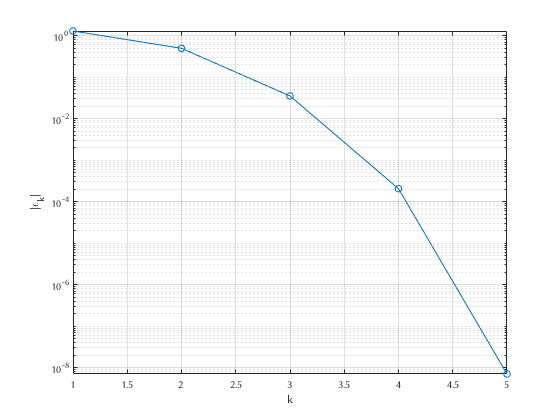

err = abs(x - r1);
clf
semilogy(err, 'o-'), axis tight, grid on
xlabel('k'), ylabel('|\epsilon_k|')

Wait, this is faster than linear convergence? Yes, but for a good reason. We discovered in the previous part that $g_1'(3) = 0$ which, according to the FPI convergence theorem, implies that

$\lim_{k \to \infty} \frac{ \vert \epsilon_{k+1} \vert }{ \vert \epsilon_{k} \vert } = \vert g'(3) \vert = 0$, superlinear convergence!

Unfortunately, this is difficult to confirm as the denominator quickly underflows (to zero):

err(2:end) ./ err(1:end-1)

ans =      3.823529411764706e-01
     7.106812447434803e-02
     5.818987735329192e-03
     3.425697871600165e-05
                         0
                       NaN
                       NaN
                       NaN
                       NaN


Moving onto $g_2$:

format long e
n = 10;
x = myfpi(g2, 1.7, n)

x =      1.700000000000000e+00
     3.389508856202910e+00
     3.080246551988983e+00
     3.156919561362624e+00
     3.137761076665939e+00
     3.142550545476954e+00
     3.141353180654625e+00
     3.141652521823013e+00
     3.141577686531497e+00
     3.141596395354367e+00


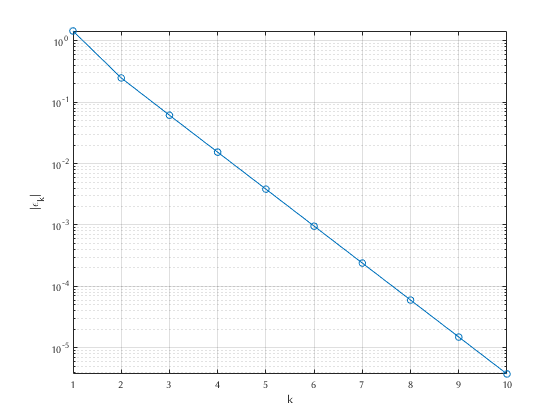

err = abs(x - r2);
clf
semilogy(err, 'o-'), axis tight, grid on
xlabel('k'), ylabel('|\epsilon_k|')

In this case, we see that the errors draw a nice straight line on the log-linear graph. Furthermore, the ratios of errors converge beautifully to the expected $\sigma = \vert g_2'(\pi) \vert = 1/4$:

err(2:end) ./ err(1:end-1)

ans =      1.719738249191035e-01
     2.474469234128392e-01
     2.498432234955372e-01
     2.499902120273960e-01
     2.499993882928684e-01
     2.499999617684353e-01
     2.499999976100850e-01
     2.499999998479356e-01
     2.499999999851645e-01


Lastly for $g_3$:

format long e
n = 15;
x = myfpi(g3, 1.7, n)

x =      1.700000000000000e+00
     2.247416847573013e+00
     2.617881264257347e+00
     2.850599005225683e+00
     2.986452451970267e+00
     3.061162389406461e+00
     3.100590041247924e+00
     3.120884031572326e+00
     3.131185104358556e+00
     3.136375386158261e+00


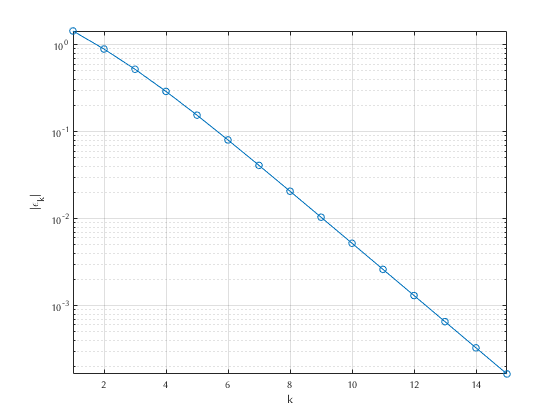

err = abs(x - r3);
clf
semilogy(err, 'o-'), axis tight, grid on
xlabel('k'), ylabel('|\epsilon_k|')

We also see that the errors draw a nice straight line on the log-linear graph. Furthermore, the ratios of errors converge beautifully to the expected $\sigma = \vert g_3'(\pi) \vert = 1/2$:

err(7:end) ./ err(6:end-1)

ans =      5.097908450034160e-01
     5.050561619051057e-01
     5.025708240006618e-01
     5.012964450721191e-01
     5.006510261133111e-01
     5.003262197391994e-01
     5.001632872715480e-01
     5.000816880784664e-01
     5.000408551610744e-01


Note that convergence is not as fast as in the previous case (even though both converge linearly) because the convergence rate $\sigma = 1/2$ for this case is larger than the previous one.

## Problem 4

### (a)

Simple Calculus 1 exercise shows that

$f'(x) = \frac{1}{2\sqrt{|x|}}$, for all $x \in \mathbb{R}$.

One Newton iteration takes any nonzero initial iterate $x_0 \neq 0$ to

$x_1 = x_0 - \frac{f(x_0)}{f'(x_0)} = x_0 - 2\text{sign}(x_0) |x_0| = -x_0$, regardless of the sign of $x_0$.

If you are unsure, examine two cases, $x_0 > 0$ and $x_0 < 0$, separately. Repeating the same computation with $x_0$ replaced by $-x_0$, we find that

$x_2 = x_1 - \frac{f(x_1)}{f'(x_1)} = -x_0 - 2\text{sign}(-x_0) |-x_0| = x_0$.

Back to the starting point! This means that the iterates generated by the Newton's iteration formula will just rock back and forth between $x_0$ and $-x_0$:


$$x_0, -x_0, x_0, -x_0, \ldots$$


a hopeless divergence scenario.

The following (minimal) Newton iteration code confirms our prediction.

f = @(x) sign(x).*sqrt(abs(x));
fprime = @(x) 1./(2*sqrt(abs(x)));
x = 1;
for k = 1:10
    x = x - f(x)/fprime(x)
end

x =     -1

x =      1

x =     -1

x =      1

x =     -1

x =      1

x =     -1

x =      1

x =     -1

x =      1

**Ponder.** Why do you think it is happening? Is it violating the convergence theorem for Newton's method?

### (b)

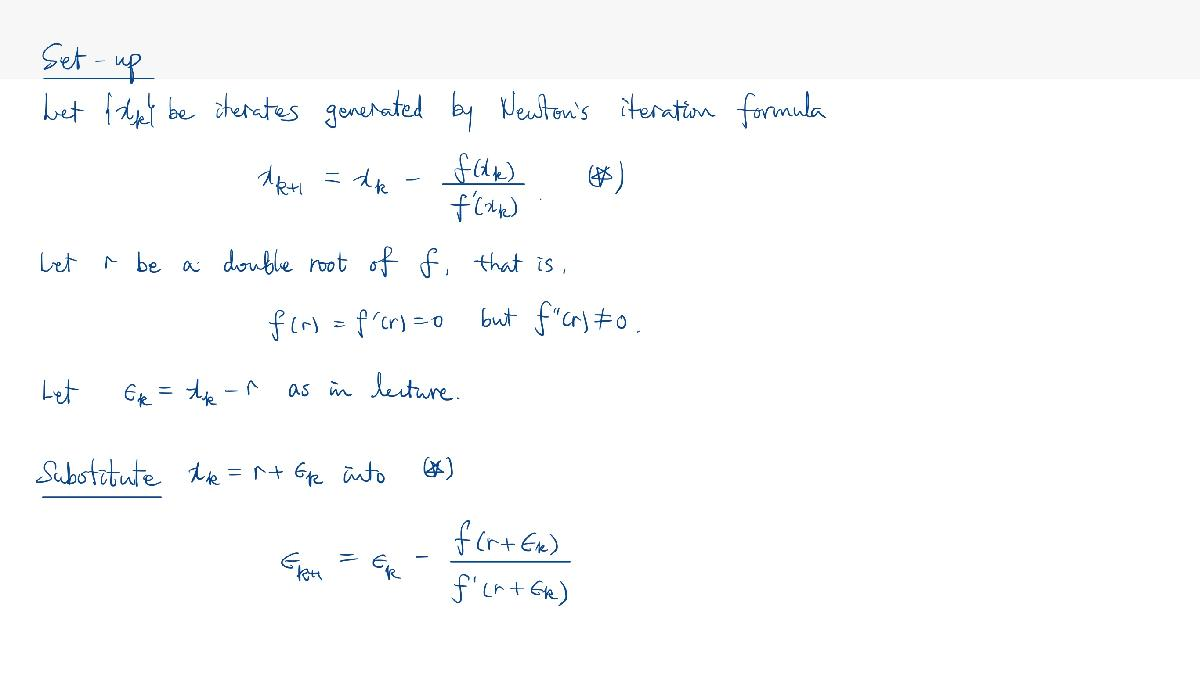

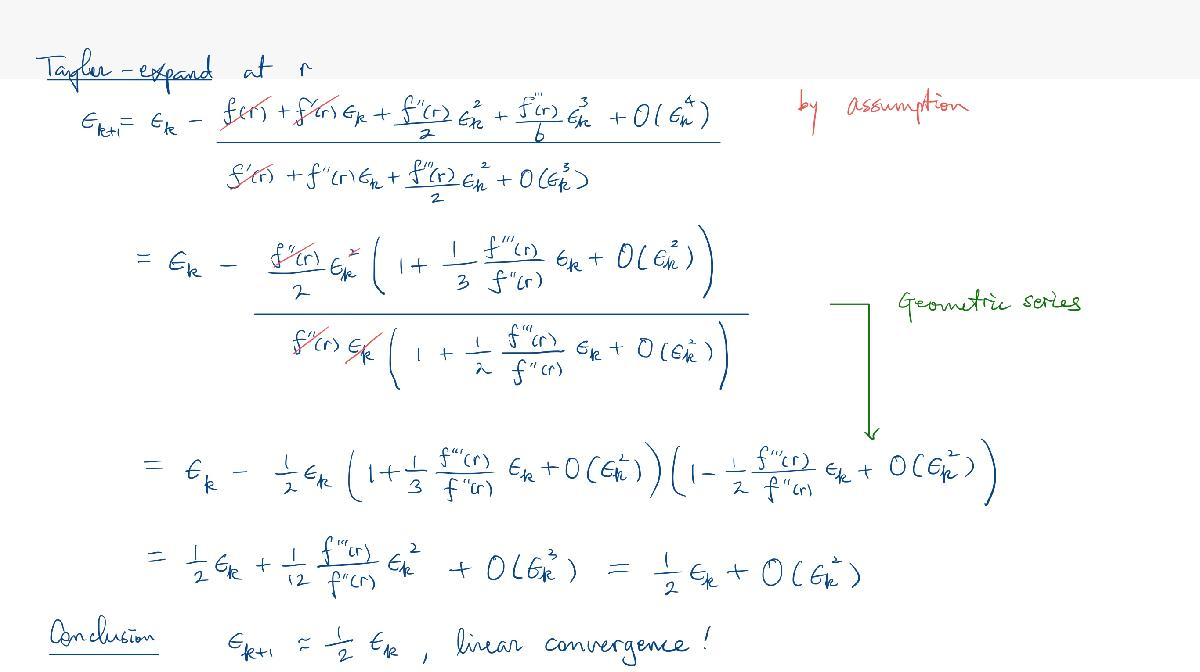

## Problem 5 (FNC 4.5.5)

### (a)

Moving all terms to one side and simplifying, we have


$$\begin{array}{rcl}
  \left(1 - \frac{\lambda}{25}\right) x - 5 & = & 0 \\
  \left(1 - \frac{\lambda}{16}\right) y - 4 & = & 0 \\
  \left(1 - \frac{\lambda}{9}\right) z - 3 & = & 0 \\
  \frac{1}{25} x^2 + \frac{1}{16}y^2 + \frac{1}{9}z^2 - 1 & = & 0
\end{array}$$


This is good enough. But for the last part, it is advantageous to write in the form $\mathbf{f}(\mathbf{u}) = \mathbf{0}$ as suggested by the problem. Let $\mathbf{u} = (u_1, u_2, u_3, u_4)^{\rm T} = (x, y, z, \lambda)^{\rm T}$, the vector consisting of all four unknowns. Then, abstractly, we may view/write the system of these four equations as a single vector equation $\mathbf{f}(\mathbf{u}) = \mathbf{0}$,  


$$
\[
  \mathbf{f}(\mathbf{u}) =
  \left[ \; \matrix{
      f_1(u_1, u_2, u_3, u_4) \cr
      f_2(u_1, u_2, u_3, u_4) \cr
      f_3(u_1, u_2, u_3, u_4) \cr
      f_4(u_1, u_2, u_3, u_4)
    }\; \right]
  =
  \left[ \; \matrix{
      (1-u_4/25) u_1 - 5 \cr
      (1-u_4/16) u_2 - 4\cr
      (1-u_4/9) u_3 - 3\cr
      u_1^2/25 + u_2^2/16 + u_3^2/9 - 1
    }\; \right]  
\]$$


simply by replacing $x, y, z, \lambda$ by $u_1, u_2, u_3, u_4$, respectively. 

### (b)

In terms of the original variables $x,y,z,\lambda$, we can express the Jacobian matrix as


$$\[
  \mathbf{J}(x,y,z,\lambda) =
  \left[ \; \matrix{
      1-\lambda/25 & 0 & 0 & -x/25 \cr
      0 & 1-\lambda/16 & 0 & -y/16 \cr
      0 & 0 & 1-\lambda/9 & -z/9 \cr
      2x/25 & 2y/16 & 2z/9 & 0
    }\; \right]
\]
$$


which can be rewritten in terms of $\mathbf{u} = (u_1, u_2, u_3, u_4)^{\rm T} =  (x,y,z,\lambda)^{\rm T}$ as

$
\[
  \mathbf{J}(\mathbf{u}) =
  \left[ \; \matrix{
      1-u_4/25 & 0 & 0 & -u_1/25 \cr
      0 & 1-u_4/16 & 0 & -u_2/16 \cr
      0 & 0 & 1-u_4/9 & -u_3/9 \cr
      2u_1/25 & 2u_2/16 & 2u_3/9 & 0
    }\; \right]
\]
$.

The latter will be useful in the next part.

### (c)

In order to use `newtonsys` to find roots of $\mathbf{f}$, we first need to write a function m-file calculating both $\mathbf{f}$ and $\mathbf{J}$. Inspired by the example in the live script accompanying Lecture 23, we write

(This function is included at the end of this live script.)

Then we are able to use `newtonsys` as follows.

format short
x1 = newtonsys(@nlsystem, [1 1 1 1])

Note that the name of the function must be passed with at-sign in its front since it is defined as an m-file. (If you defined a function in-line as an anonymous function, the at-sign is unnecessary.)

To find another solution, use a different initial guess. 

x2 = newtonsys(@nlsystem, [-1 -1 -1 1])

**Check.** Are the solutions really on the ellipsoid?

eq_ellips = @(u) u(1)^2/25 + u(2)^2/16 + u(3)^2/9 - 1;

x1 =     1.0000    4.6945    3.5843    3.4311    3.4241    3.4241    3.4241
    1.0000    3.4446    2.4818    2.3311    2.3268    2.3268    2.3268
    1.0000    1.8336    1.4283    1.3186    1.3167    1.3167    1.3167
    1.0000  -11.3310  -10.2192  -11.3800  -11.5053  -11.5056  -11.5056


p1 = x1(1:3,end);
p2 = x2(1:3,end);
format short e
[eq_ellips(p1), eq_ellips(p2)]'

x2 =    -1.0000    2.1306   -0.8437  -11.7432   -6.6115   -4.7672   -4.4169   -4.4038   -4.4037   -4.4037
   -1.0000   -0.6577   -1.5221   -3.5260   -2.5298   -1.8132   -1.7221   -1.7119   -1.7119   -1.7119
   -1.0000   -5.8583   -3.8719   -1.5987   -0.7062   -0.6950   -0.6045   -0.6084   -0.6083   -0.6083
    1.0000   74.8662   35.9427   31.7917   38.6124   47.7038   52.8890   53.3832   53.3850   53.3850


Yes, they are!

**Closest or Farthest?**

One of the two solutions have all positive components while the other has all negative components. The former should be closest while the latter farthest, because the given point $(5,4,3)$ lies in the first octant. 

Run the following script and rotate the generated 3-D figure around to stop the closest and the farthest points. 

nr_th = 31;
nr_ph = 41;
th = linspace(0, 2*pi, nr_th);
ph = linspace(0, pi, nr_ph);
[TH,PH] = meshgrid(th, ph);

ans =             0
   2.2204e-16


a = 5; b = 4; c = 3;
x = a*sin(PH).*cos(TH);
y = b*sin(PH).*sin(TH);
z = c*cos(PH);
clf
surf(x,y,z), hold on, axis equal
xlabel('x'), ylabel('y'), zlabel('z')
plot3(5,4,3, 'b.', 'MarkerSize', 30)
plot3(p1(1), p1(2), p1(3), 'r.', 'MarkerSize', 30)
plot3(p2(1), p2(2), p2(3), 'k.', 'MarkerSize', 30)
legend('ellipsoid', '(5,4,3)', '1st solution', '2nd solution')

view([62 25])   % better viewing angle for the first solution

view([-40 15])  % better viewing angle for the second solution

## Functions Used

### Lambert's W function

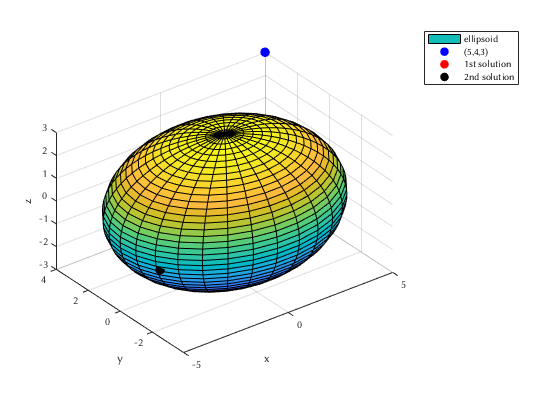

function y = lambertW(x)
% LAMBERT y = lambertW(x)
% Evaluate Lambert's W function y = W(x)
% by solving x = y*exp(y).
% 
% Input:
%   x    an array input
% Output:
%   y    W(x)

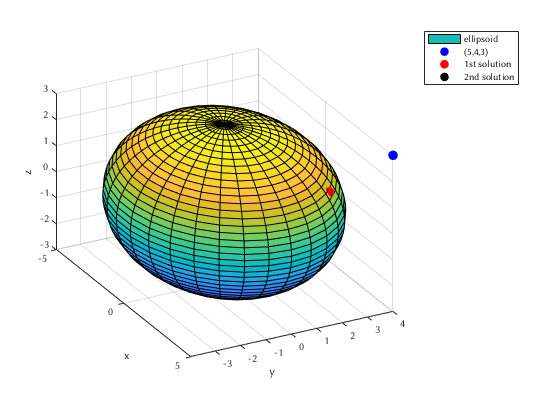

    y = zeros(size(x));
    for j = 1:numel(x)

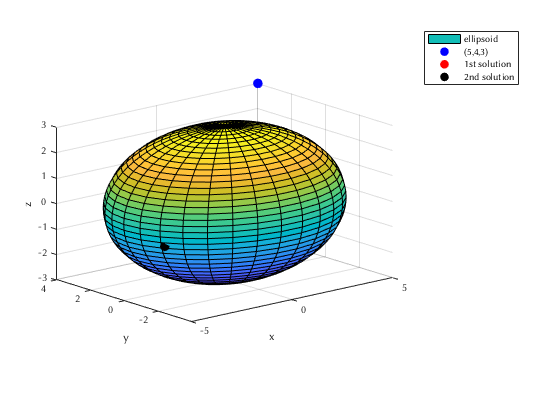

        y(j) = fzero( @(y) x(j) - y*exp(y), 1 );
    end

end

### Fixed Point Iteration

function x = myfpi(g, x0, n)
% Generates fixed point iterates x_0, x_1, ..., x_{n-1}.
% All iterates are stored in a single (column) vector x.
    x = zeros(n, 1);
    x(1) = x0;
    for k = 1:n-1
        x(k+1) = g(x(k));
    end
end

### Newton Iteration for Systems

function x = newtonsys(f,x1)
% NEWTONSYS   Newton's method for a system of equations.
% Input:
%   f        function that computes residual and Jacobian matrix
%   x1       initial root approximation (n-vector)
% Output
%   x        array of approximations (one per column, last is best)

% Operating parameters.
    funtol = 1000*eps;  xtol = 1000*eps;  maxiter = 40;

    x = x1(:);
    [y,J] = f(x1);
    dx = Inf;
    k = 1;

    while (norm(dx) > xtol) && (norm(y) > funtol) && (k < maxiter)
        dx = -(J\y);   % Newton step
        x(:,k+1) = x(:,k) + dx;

        k = k+1;
        [y,J] = f(x(:,k));
    end

    if k==maxiter, warning('Maximum number of iterations reached.'), end
end

### Residual and Jacobian function for #5

function [f,J] = nlsystem(u)
    f = [ (1-u(4)/25)*u(1) - 5;
          (1-u(4)/16)*u(2) - 4;
          (1-u(4)/9)*u(3) - 3;
          u(1)^2/25 + u(2)^2/16 + u(3)^2/9 - 1];
    J = [ 1-u(4)/25, 0, 0, -u(1)/25;
          0, 1-u(4)/16, 0, -u(2)/16;
          0, 0, 1-u(4)/9,  -u(3)/9;
          2*u(1)/25, 2*u(2)/16, 2*u(3)/9, 0];
end